## Code Structure

Signal Generation - Shows code for generating a example downlink frame containing pss and sss 

Channel Effects - Shows code for adding channel effects to signal generated

PSS Detection - Shows code for detecting pss from signal

Timing Offset Correction - Shows code to correct timing offset of signal

Frequency Offset Correction - Shows code to correct frequency offset of signal

SSS Detection - Shows code for detecting sss from the corrected signal

SNR Plotting - Using the above code we plot detection probability, freq error, timing error on selected SNR values

Fuctions - Defines the functions used

## Signal Generation

% Generate a LTE Radio Frame

cyclic_prefix = 'Normal';
ndlrb = 6;
cell_refp = 1;
duplex_mode = 'FDD';
sampling_rate = 1.92e6;
display = true;

[tx, tx_grid, real_pss_id, real_sss_id, enb] = SignalGenerate(cyclic_prefix, ndlrb, cell_refp, duplex_mode);
fprintf('Real PSS ID = %d\n', real_pss_id)

Real PSS ID = 1


fprintf('Real SSS ID = %d\n', real_sss_id)

Real SSS ID = 12


## Channel Effects

% Received
rx = tx;

% Adding AWGN Noise
SNR = 10;
rx = awgn(rx, SNR, 'measured');

% Adding Rayleigh Fading
rayleigh_chan = comm.RayleighChannel('SampleRate', sampling_rate, 'PathDelays', 0, 'AveragePathGains', 0);
rx = rayleigh_chan(rx);

% Adding Timing Offset
info = lteOFDMInfo(enb);
cyclic_prefix_length = info.CyclicPrefixLengths;
timing_offset = randi([0 cyclic_prefix_length(1)-1]);
rx = [zeros(timing_offset, 1); rx(1:end-timing_offset)];
fprintf('Real Timing Offset = %d\n', timing_offset)

Real Timing Offset = 7



%Adding Frequency Offset
frequency_offset = (rand*10000) - 5000;
rx = rx.*exp(1i*2*pi*frequency_offset/sampling_rate * (0:length(rx)-1)');
fprintf('Real Frequency Offset = %d\n', frequency_offset)

Real Frequency Offset = -1.548517e+03


## PSS Detection

[detectedPSS, detected_timing_offset, max_corr_value] = PSSDetection(enb, rx, display);

Detected PSS Identity: 1
Highest Correlation Location : 827
Detected Timing Offset : 7
Highest Correlation Value : 9.273962e-02


## Timing Offset Correction

rx = [rx(detected_timing_offset+1:end); zeros(detected_timing_offset, 1)];

## Frequency Offset Correction

[estimated_frequency_offset] = FrequencyOffsetEstimation(rx, enb)

estimated_frequency_offset = -1.5713e+03

[corrected_signal] = FrequencyOffsetCorrection(rx, estimated_frequency_offset, sampling_rate);
rx_grid_corrected = lteOFDMDemodulate(enb, corrected_signal);

## SSS Detection

[detectedSSS, corr_value] = SSSDetection(enb, rx, detectedPSS, display);

Detected SSS If Subframe 0 Identity: 13
Highest Correlation Value : 1.141198e-01
Detected SSS If Subframe 5 Identity: 12
Highest Correlation Value : 2.389013e-01
Final SSS Detected and Subframe : 12 , 5


## SNR Plotting 

SNR_DB = -50:0.5:20;
runs = 30;
display = false;

% Define Plotting Variables
pss_detect_probability_plot = [];
sss_detect_probability_plot = [];
frequency_error_plot = [];
timing_error_plot = [];
for i=1:length(SNR_DB)
    % Define Stats Variables
    detected_pss_count = 0;
    detected_sss_count = 0;
    frequency_error_total = 0;
    timing_error_total = 0;

    detected_pss_probability = 0;
    detected_sss_probability = 0;
    frequency_error_avg = 0;
    timing_error_avg = 0;

    for run=1:runs
        % Generate Signal
        [tx, tx_grid, real_pss_id, real_sss_id, enb] = SignalGenerate(cyclic_prefix, ndlrb, cell_refp, duplex_mode);
        rx = tx;

        % Channel Effects - AWGN
        rx = awgn(rx, SNR_DB(i), 'measured');

        % Channel Effect - Rayleigh Fading
        rayleigh_chan = comm.RayleighChannel('SampleRate', sampling_rate, 'PathDelays', 0, 'AveragePathGains', 0);
        rx = rayleigh_chan(rx);


        % Channel Effects - Timing Offset
        info = lteOFDMInfo(enb);
        cyclic_prefix_length = info.CyclicPrefixLengths;
        timing_offset = randi([0 cyclic_prefix_length(1)-1]);
        rx = [zeros(timing_offset, 1); rx(1:end-timing_offset)];
        
        % Channel Effects - Frequency Offset
        frequency_offset = (rand*10000) - 5000;
        rx = rx.*exp(1i*2*pi*frequency_offset/sampling_rate * (0:length(rx)-1)');

        % PSS Detection
        [detectedPSS, detected_timing_offset, max_corr_value] = PSSDetection(enb, rx, display);

        % Timing Offset Correction
        rx = [rx(detected_timing_offset+1:end); zeros(detected_timing_offset, 1)];

        % Frequecy Offset Correction
        [estimated_frequency_offset] = FrequencyOffsetEstimation(rx, enb);
        [rx] = FrequencyOffsetCorrection(rx, estimated_frequency_offset, sampling_rate);

        % SSS Detection
        [detectedSSS, corr_value] = SSSDetection(enb, rx, detectedPSS, display);

        % Update Stats Variables - PSS Detection Count
        if detectedPSS == real_pss_id
            detected_pss_count = detected_pss_count + 1;
        else
            detected_pss_count = detected_pss_count;
        end

        % Update Stats Variables - SSS Detection Count
        if detectedSSS == real_sss_id
            detected_sss_count = detected_sss_count + 1;
        else
            detected_sss_count = detected_sss_count;
        end
    
        % Update Stats Variables - Frequency Error Total
        frequency_error_total = frequency_error_total + abs(frequency_offset - estimated_frequency_offset);

        % Update Stats Variables - Timing Error Total
        timing_error_total = timing_error_total + abs(timing_offset - detected_timing_offset);
    end
    
    % Update Stats Variables
    detected_pss_probability = detected_pss_count/runs;
    detected_sss_probability = detected_sss_count/runs;
    frequency_error_avg = frequency_error_total/runs;
    timing_error_avg = timing_error_total/runs;

    % Update Plotting Variables
    pss_detect_probability_plot = [pss_detect_probability_plot, detected_pss_probability];
    sss_detect_probability_plot = [sss_detect_probability_plot, detected_sss_probability];
    frequency_error_plot = [frequency_error_plot, frequency_error_avg];
    timing_error_plot = [timing_error_plot ,timing_error_avg];

    % Loop Progress 
    if mod(i,10)==0
        fprintf('At SNR Index %d out of %d\n', i, length(SNR_DB))
    end
end

At SNR Index 10 out of 141
At SNR Index 20 out of 141
At SNR Index 30 out of 141
At SNR Index 40 out of 141
At SNR Index 50 out of 141
At SNR Index 60 out of 141
At SNR Index 70 out of 141
At SNR Index 80 out of 141
At SNR Index 90 out of 141
At SNR Index 100 out of 141
At SNR Index 110 out of 141
At SNR Index 120 out of 141
At SNR Index 130 out of 141
At SNR Index 140 out of 141


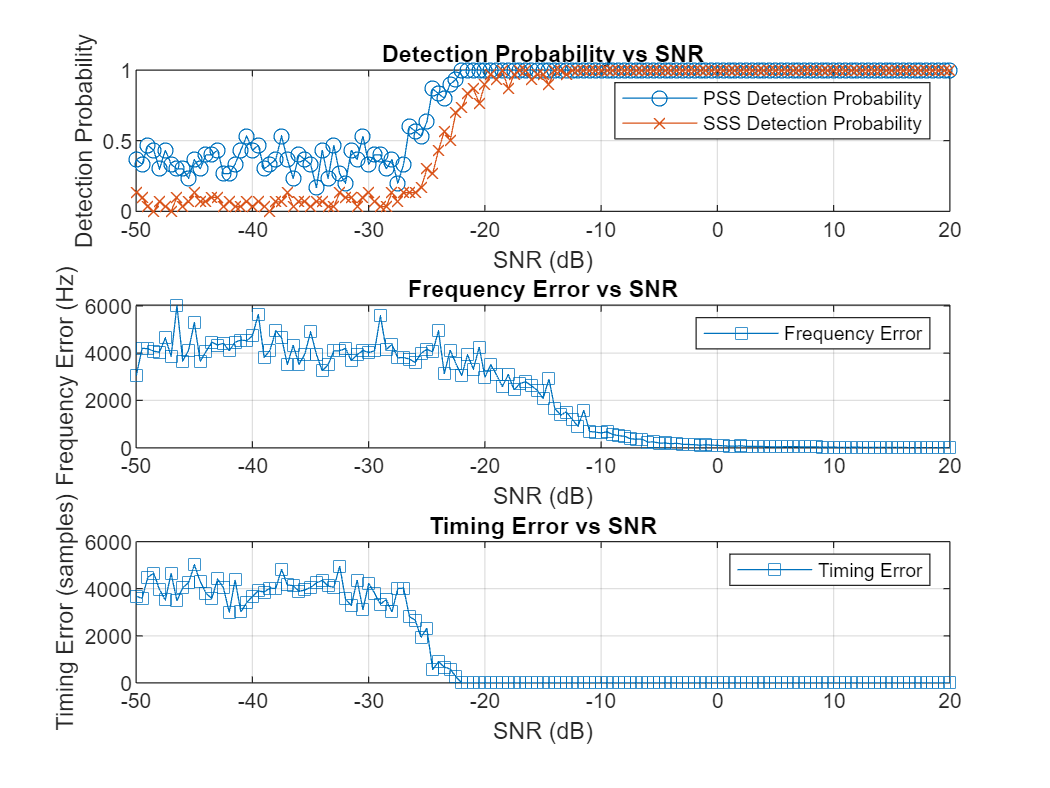


% Plot Results
figure;

% Subplot For PSS and SSS Detection Probability
subplot(3,1,1);
plot(SNR_DB, pss_detect_probability_plot, '-o', 'DisplayName', 'PSS Detection Probability');
hold on;
plot(SNR_DB, sss_detect_probability_plot, '-x', 'DisplayName', 'SSS Detection Probability');
xlabel('SNR (dB)');
ylabel('Detection Probability');
title('Detection Probability vs SNR');
legend('show');
grid on;

% Subplot For Frequency Error
subplot(3,1,2); 
plot(SNR_DB, frequency_error_plot, '-s', 'DisplayName', 'Frequency Error');
xlabel('SNR (dB)');
ylabel('Frequency Error (Hz)');
title('Frequency Error vs SNR');
legend('show');
grid on;

% Subplot For Timing Error
subplot(3,1,3); 
plot(SNR_DB, timing_error_plot, '-s', 'DisplayName', 'Timing Error');
xlabel('SNR (dB)');
ylabel('Timing Error (samples)');
title('Timing Error vs SNR');
legend('show');
grid on;

## Function Defintions

function [tx, tx_grid, real_pss_id, real_sss_id, enb] = SignalGenerate(cyclic_prefix, ndlrb, cell_refp, duplex_mode)

    % Set basic config
    enb.CyclicPrefix = cyclic_prefix;
    enb.NDLRB = ndlrb;
    enb.CellRefP = cell_refp;
    enb.DuplexMode = duplex_mode;

    % Choose transmisson cell id
    PSS_ID = randi([0, 2]);
    real_pss_id = PSS_ID;
    SSS_ID = randi([0, 15]);
    real_sss_id = SSS_ID;
    enb.NCellID = 3*SSS_ID + PSS_ID;
    
    % Iterate through subframe to make radio frame
    tx_grid = [];
    for i=0:9
        enb.NSubframe = i;
        subframe = lteDLResourceGrid(enb);

        pss = ltePSS(enb);
        sss = lteSSS(enb);
        pss_indices = ltePSSIndices(enb, 0);
        sss_indices = lteSSSIndices(enb, 0);

        subframe(pss_indices) = pss;                                % Set PSS in the grid
        subframe(sss_indices) = sss;                                % Set SSS in the grid

        if enb.NSubframe == 0
            subframe(:, 2) = 1;                                     % Set all REs in second OFDM symbol to 1 for testing
        end

        tx_grid = [tx_grid subframe];
        [tx, ~] = lteOFDMModulate(enb, tx_grid);
    end

end

function [detectedPSS, detected_timing_offset, max_corr_value] = PSSDetection(enb, rx, display)
    domain = 'time';
    [pss_matrix] = PSSSyncSignalMatrix(domain, enb);
    pss_length = size(pss_matrix, 1);
    correlation_results = zeros(length(rx)/2-pss_length+1, 3);
    
    for i = 1:3
        for shift = 1:length(rx)/2-pss_length+1
            segment = rx(shift:shift+pss_length-1);
            correlation_results(shift,i) = correlateSignals(pss_matrix(:,i), segment);
        end
    end
    
    [max_corr_signal_value, max_corr_signal_index] = max(correlation_results, [], 1);
    [~, max_corr_pss_index] = max(max(correlation_results, [], 1));
    
    detectedPSS = max_corr_pss_index - 1; 
    detected_timing_offset = abs(max_corr_signal_index(max_corr_pss_index) - 820);
    max_corr_value = max_corr_signal_value(max_corr_pss_index);

    if display == true
        fprintf('Detected PSS Identity: %d\n', detectedPSS);
        fprintf('Highest Correlation Location : %d\n', max_corr_signal_index(max_corr_pss_index));
        fprintf('Detected Timing Offset : %d\n', detected_timing_offset);
        fprintf('Highest Correlation Value : %d\n', max_corr_signal_value(max_corr_pss_index));
    end
end




    
function [detectedSSS, corr_value] = SSSDetection(enb, rx, detectedPSS, display)
    domain = 'time';
    [sss_matrix_subframe0, sss_matrix_subframe5] = SSSSyncSignalMatrix(domain, enb, detectedPSS);
    
    % Subframe 0
    sss_length = size(sss_matrix_subframe0, 1);
    correlation_results = zeros(length(rx)-sss_length+1, 3);
    
    for i = 1:16
        for shift = 9600:9600+960
            segment = rx(shift:shift+sss_length-1);
            correlation_results(shift,i) = correlateSignals(sss_matrix_subframe0(:,i), segment);
        end
    end
    
    [max_corr_signal_value, ~] = max(correlation_results, [], 1);
    [~, max_corr_sss_index] = max(max(correlation_results, [], 1));
    
    detectedSSS_sub0 = max_corr_sss_index - 1; 
    sub0_corr_value = max_corr_signal_value(max_corr_sss_index);

    if display == true
        fprintf('Detected SSS If Subframe 0 Identity: %d\n', detectedSSS_sub0);
        fprintf('Highest Correlation Value : %d\n',  abs(max_corr_signal_value(max_corr_sss_index)));
    end

    % Subframe 5
    sss_length = size(sss_matrix_subframe5, 1);
    correlation_results = zeros(length(rx)-sss_length+1, 3);
    
    for i = 1:16
        for shift = 9600:9600+960
            segment = rx(shift:shift+sss_length-1);
            correlation_results(shift,i) = correlateSignals(sss_matrix_subframe5(:,i), segment);
        end
    end
    
    [max_corr_signal_value, ~] = max(correlation_results, [], 1);
    [~, max_corr_sss_index] = max(max(correlation_results, [], 1));
    
    detectedSSS_sub5 = max_corr_sss_index - 1;
    sub5_corr_value = max_corr_signal_value(max_corr_sss_index);

    if display == true
        fprintf('Detected SSS If Subframe 5 Identity: %d\n', detectedSSS_sub5);
        fprintf('Highest Correlation Value : %d\n',  abs(max_corr_signal_value(max_corr_sss_index)));
    end

    % Final Detection
    if abs(sub5_corr_value) > abs(sub0_corr_value)
        detectedSSS = detectedSSS_sub5;
        corr_value = sub5_corr_value;
        if display == true
            fprintf('Final SSS Detected and Subframe : %d , 5\n', detectedSSS)
        end
    end
    if abs(sub5_corr_value) <= abs(sub0_corr_value)
        detectedSSS = detectedSSS_sub0;
        corr_value = sub0_corr_value;
        if display == true
            fprintf('Final SSS Detected : %d , 0\n', detectedSSS)
        end
    end

end

function [pss_matrix] = PSSSyncSignalMatrix(domain, enb)

    enb.NSubframe = 0;
    
    pss_matrix = [];
    
    % PSS Matrix for PSS_IDs 0, 1, 2
    for pss_id = 0:2
        enb.NCellID = pss_id; 
        pss_freq = ltePSS(enb);
        
        if strcmp(domain, 'time')
            grid = lteDLResourceGrid(enb);
            pss_indices = ltePSSIndices(enb);
            grid(pss_indices) = pss_freq;
            
            pss_time = lteOFDMModulate(enb, grid);
            first_nonzero_index = find(pss_time, 1, 'first');
            last_nonzero_index = find(pss_time, 1, 'last');
            pss_time = pss_time(first_nonzero_index:last_nonzero_index);
            pss_matrix = [pss_matrix, pss_time];

        elseif strcmp(domain, 'frequency')
            pss_matrix = [pss_matrix, pss_freq];
        end
    end
end

   
function [sss_matrix_subframe0, sss_matrix_subframe5] = SSSSyncSignalMatrix(domain, enb, detectedPSS)

    sss_matrix_subframe0 = [];
    sss_matrix_subframe5 = [];
    for sss_id = 0:15
        enb.NCellID = 3*sss_id + detectedPSS;
        enb.NSubframe = 0;
        
        sss_freq = lteSSS(enb); 
        
        if strcmp(domain, 'time')
            grid = lteDLResourceGrid(enb);
            sss_indices = lteSSSIndices(enb);
            grid(sss_indices) = sss_freq;
            
            sss_time = lteOFDMModulate(enb, grid);
            first_nonzero_index = find(sss_time, 1, 'first');
            last_nonzero_index = find(sss_time, 1, 'last');
            sss_time = sss_time(first_nonzero_index:last_nonzero_index);
            sss_matrix_subframe0 = [sss_matrix_subframe0, sss_time];
        elseif strcmp(domain, 'frequency')
            sss_matrix_subframe0 = [sss_matrix_subframe0, sss_freq];
        end
    end

    for sss_id = 0:15
        enb.NCellID = 3*sss_id + detectedPSS;
        enb.NSubframe = 5;
        
        sss_freq = lteSSS(enb); 
        
        if strcmp(domain, 'time')
            grid = lteDLResourceGrid(enb);
            sss_indices = lteSSSIndices(enb);
            grid(sss_indices) = sss_freq;
            
            sss_time = lteOFDMModulate(enb, grid);
            first_nonzero_index = find(sss_time, 1, 'first');
            last_nonzero_index = find(sss_time, 1, 'last');
            sss_time = sss_time(first_nonzero_index:last_nonzero_index);
            sss_matrix_subframe5 = [sss_matrix_subframe5, sss_time];
        elseif strcmp(domain, 'frequency')
            sss_matrix_subframe5 = [sss_matrix_subframe5, sss_freq];
        end
    end
end

function [correlation] = correlateSignals(signal1, signal2)
    correlation = 0;
    for i = 1:length(signal1)
        correlation = correlation + conj(signal1(i))*signal2(i);
    end
end

function [estimated_frequency_offset, corr] = FrequencyOffsetEstimation(rx, enb)
    % Done Using Correlation Between Cyclic Prefix
    info=lteOFDMInfo(enb);
    nFFT=double(info.Nfft);
    tFFT=1/15000;
    samplesPerSlot=info.SamplingRate*0.5e-3;
    estimated_frequency_offset=0;
    cpLengths=double(info.CyclicPrefixLengths);
    cpLengths=cpLengths(1:length(cpLengths)/2);
    cpLength=cpLengths(2);

    symbolStarts=cumsum(cpLengths+nFFT);
    symbolStarts0=[0 symbolStarts(1:end-1)];    
        
    arm1=rx(1:end-nFFT);
    arm2=rx(1+nFFT:end);

    cpcorrunfilt=arm1.*conj(arm2);
    cpcorr=conv(cpcorrunfilt,ones(cpLength,1));
    cpcorr=cpcorr(cpLength:end);  

    cpcorravg=cpcorr(1:(fix(length(cpcorr)/samplesPerSlot)*samplesPerSlot)); 
    nSlots=length(cpcorravg)/(samplesPerSlot);
    cpcorravg=sum(reshape(cpcorravg,samplesPerSlot,length(cpcorravg)/samplesPerSlot),2);  
    cpcorrmag=abs(cpcorravg);   
    corr(:)=cpcorrmag;
    
    idx=1:1:length(cpcorrmag);
    cycshift=0;
    tail=samplesPerSlot-symbolStarts0(end);
    cycshift=mod(cycshift+tail,samplesPerSlot)-tail;
    candidates=-symbolStarts0+cycshift;
    candidateidxs=1:length(symbolStarts0);
    pos=candidateidxs(abs(candidates)==min(abs(candidates)));
    cycshift=min(candidates(pos));
    
    freqIdxs=[];
    link='Downlink';
    for l=1:nSlots                           
        info=lteDuplexingInfo(enb);
        if (strcmpi(info.SubframeType,link)==1)
            freqIdxs=[freqIdxs samplesPerSlot*(l-1)+symbolStarts];
        else
            if (~isempty(freqIdxs))
                freqIdxs(end)=[];
            end
        end
        if (mod(l,2)==0 && strcmpi(enb.DuplexMode,'TDD')==1)
            enb.NSubframe=mod(enb.NSubframe+1,10);
        end
    end
     if (~isempty(freqIdxs)) 
        freqIdxs(end)=[];
        estimates=[];
        for add=fix(cpLength/4):fix(cpLength*3/4)-1
            estimates=[estimates; cpcorrunfilt(cycshift+freqIdxs+add)];
        end           
    
        estimated_frequency_offset=-angle(mean(estimates))/(2*pi*tFFT);  
     end
end

function [corrected_signal] = FrequencyOffsetCorrection(signal, estimated_frequency_offset, sampling_rate)
    correction = exp(-1i*2*pi*estimated_frequency_offset/sampling_rate * (0:length(signal)-1)');
    corrected_signal = signal.*correction;
end

## END